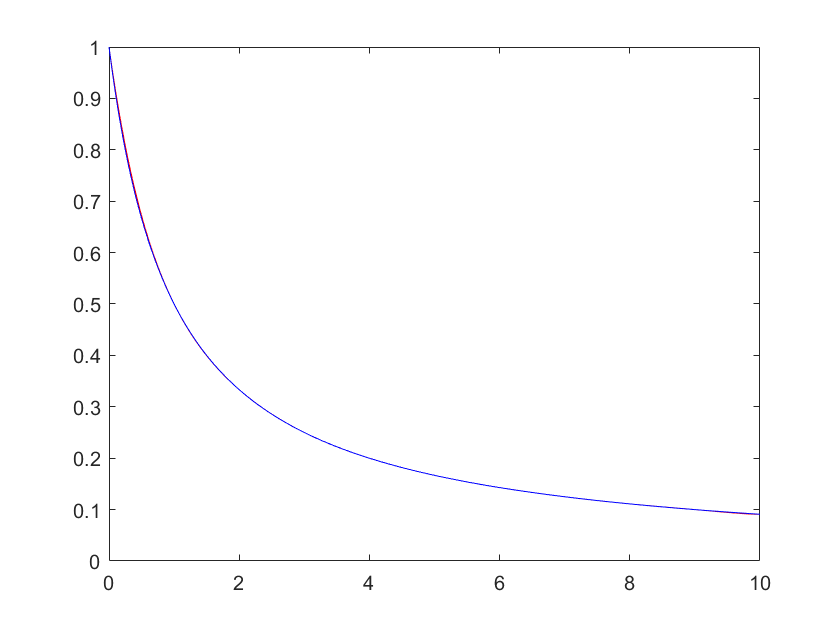

x=[0,1,2,3,4,5,6,7,8,9,10];
t=linspace(0,10,200);
p=lagrange(x,1./(1+x),t);
plot(t,p,'-r',t,1./(1+t),'-b')

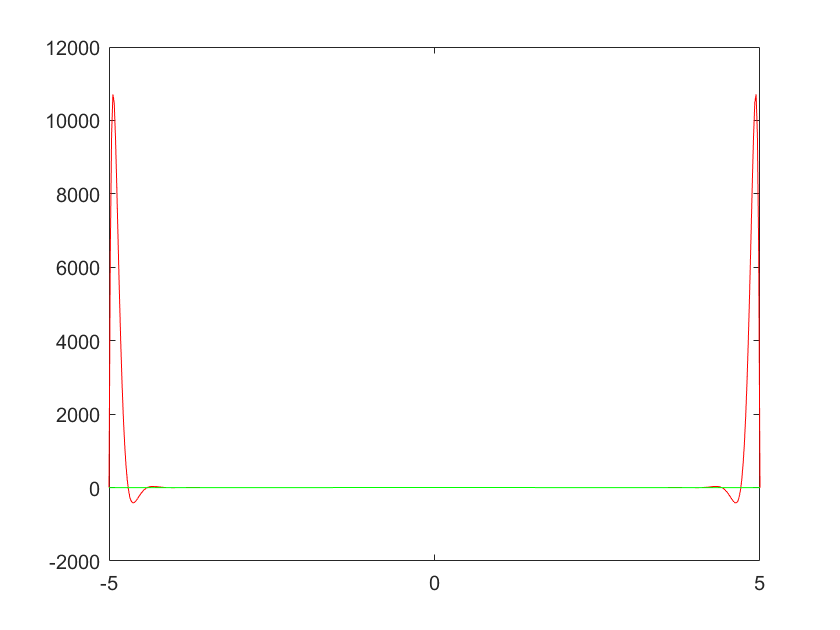

x=linspace(-5,5,35);
xx=5.*cos((pi/35).*(0:34));
t=linspace(-5,5,500);
p2=newton(x,1./(1+x.^2),t);
p3=newton(xx,1./(1+xx.^2),t);
plot(t,p2,'-r',t,1./(1+t.^2),'-b',t,p3,'-g');

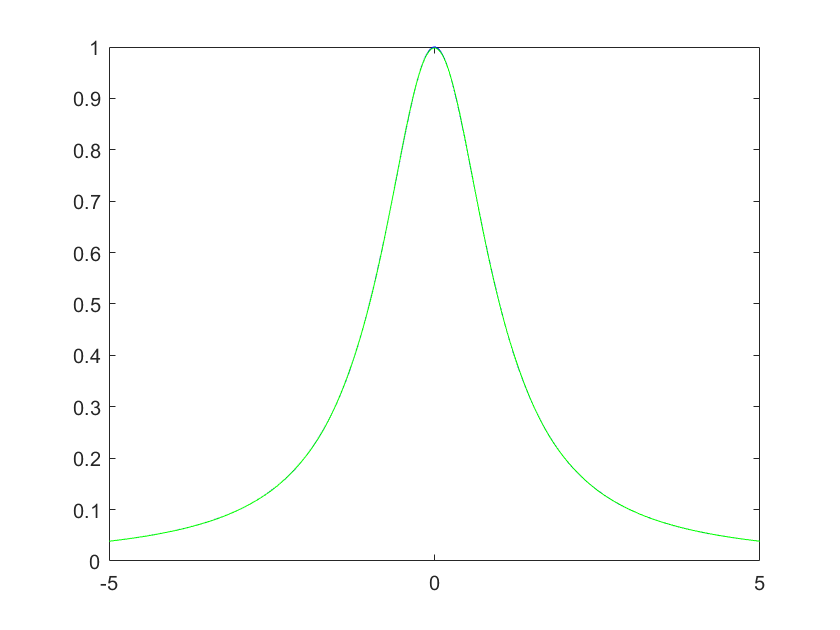

plot(t,1./(1+t.^2),'-b',t,p3,'-g');

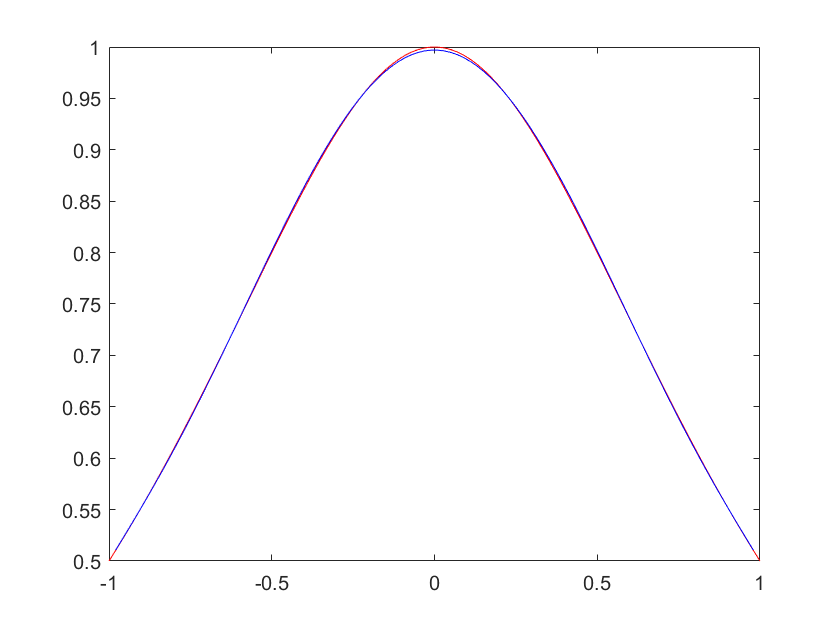

f=@(x)1./(1+x.^2);
n=7;
t=linspace(-1,1,100);
p4=chebyg(f,n,t);
plot(t,f(t),'-r',t,p4,'-b');

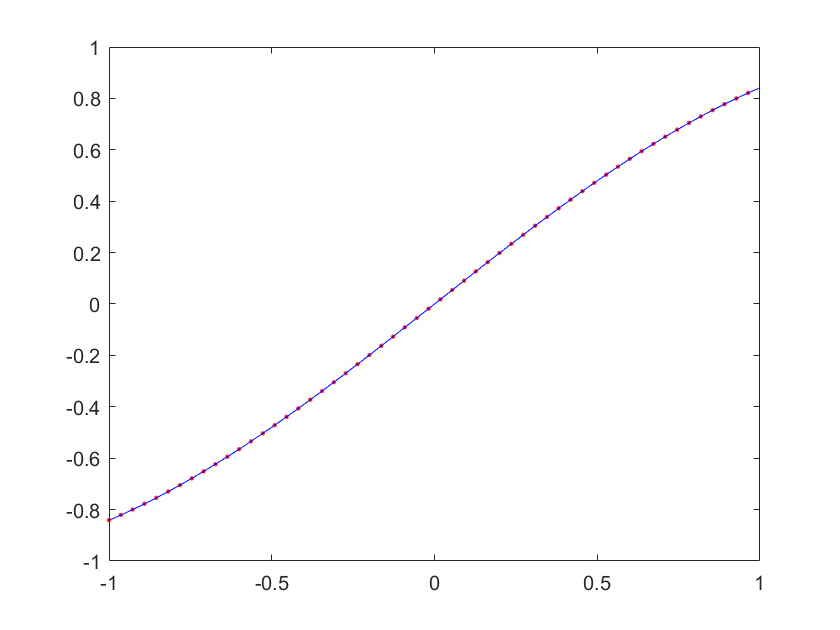

n=3;
x=cos((0:n-1)*pi/n);
y=sin(x);
dy=cos(x);
t=linspace(-1,1,56);
h=hermite(x,y,dy,t);
plot(t,h,'.r',t,sin(t),'-b')